## Clément interpolator implementation

### Preliminars

Mesh on which the *given* (or input) function will be projected and filtered. Consider the following discretization of a [0,1]x[0,1] domain:

clear;
x1 = linspace(0,1,50);
x2 = linspace(0,1,50);

[xv,yv] = meshgrid(x1,x2);

[F,V] = mesh2tri(xv,yv,zeros(size(xv)),'x');

m.coord  = V(:,1:2);
m.connec = F;
mesh     = Mesh.create(m);

Moreover, we need a *given L2 *function:

s.fHandle = @(x) 1-heaviside((x(1,:,:)-0.5).^2+(x(2,:,:)-0.5).^2-0.3.^2);
s.ndimf   = 1;
s.mesh    = mesh;
fun       = AnalyticalFunction(s);
funToP1   = fun.project('P1');

iPar.mesh     = mesh;
iPar.quadType = 'QUADRATICMASS';
error         = IntegratorError(iPar);

### Interpolating

Let's interpolate previous L2 function:

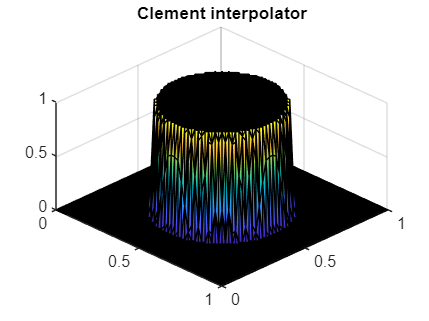

s = [];
s.mesh = mesh;
interp = ClementInterpolator(s);
xInt   = interp.compute(fun,'QUADRATICMASS');

xInt.plot();
view(45,45);
title('Clement interpolator');

error.compute(xInt,fun)

ans = 0.0018

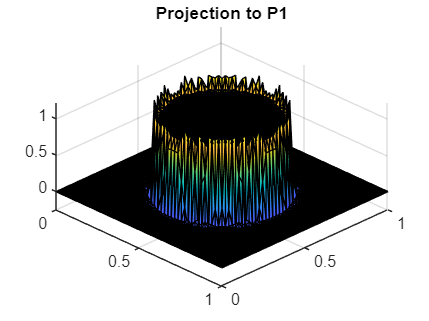


funToP1.plot();
view(45,45);
title('Projection to P1')